clear all;
clc;

## Radar Specifications

%%%%%%%%%%%%%%%%%%%%%%%%%%%
frequencyOfOperation = 77; %GHz
maxRange = 200; %m
rangeResolution = 1; %m
maxVelocity = 100; %m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

speedOfLight = 3e8;

## User Defined Range and Velocity of target

initialRange = 20; %m
initialVelocity = 50; %m/s

## FMCW Waveform Generation

% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of FMCW
B = speedOfLight / (2 * rangeResolution);
Tchirp = (5.5 * 2 * maxRange) / speedOfLight;
slope = B/Tchirp;

%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq

                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

## Signal generation and Moving Target simulation

Running the radar scenario over the time. 

for i=1:length(t)         
    currentTime = t(i);
    
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = initialRange + initialVelocity * currentTime; % distance = speed * time
    td(i) = r_t(i) / speedOfLight * 2; % time to object = distance / speed of light * 2 (since wave goes and comes back)
    
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2*pi * (fc * currentTime + (slope * currentTime^2)/2));
    timeDifference = (currentTime - td(i));
    Rx(i) = cos(2*pi * (fc * timeDifference + (slope * timeDifference^2)/2));
    
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i).*Rx(i);
    
end

## RANGE MEASUREMENT

%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Mix = reshape(Mix, [Nr, Nd]); % [number of rows (Nr), number of columns (Nd)]

%run the FFT on the beat signal along the range bins dimension (Nr)
fftAlongNr = fft(Mix);

% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples before additional computation
fftAlongNr = fftAlongNr(1:floor(length(fftAlongNr)/2), :);

% Take the absolute value of FFT output and normalize
fftAlongNrAbsolute = abs(fftAlongNr);
fftAlongNrAbsoluteNormalized = fftAlongNrAbsolute./max(fftAlongNrAbsolute);

%plotting the range
oneDimensionalFFTPlot = figure ('Name','Range from First FFT')

oneDimensionalFFTPlot =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 1
        Name: 'Range from First FFT'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


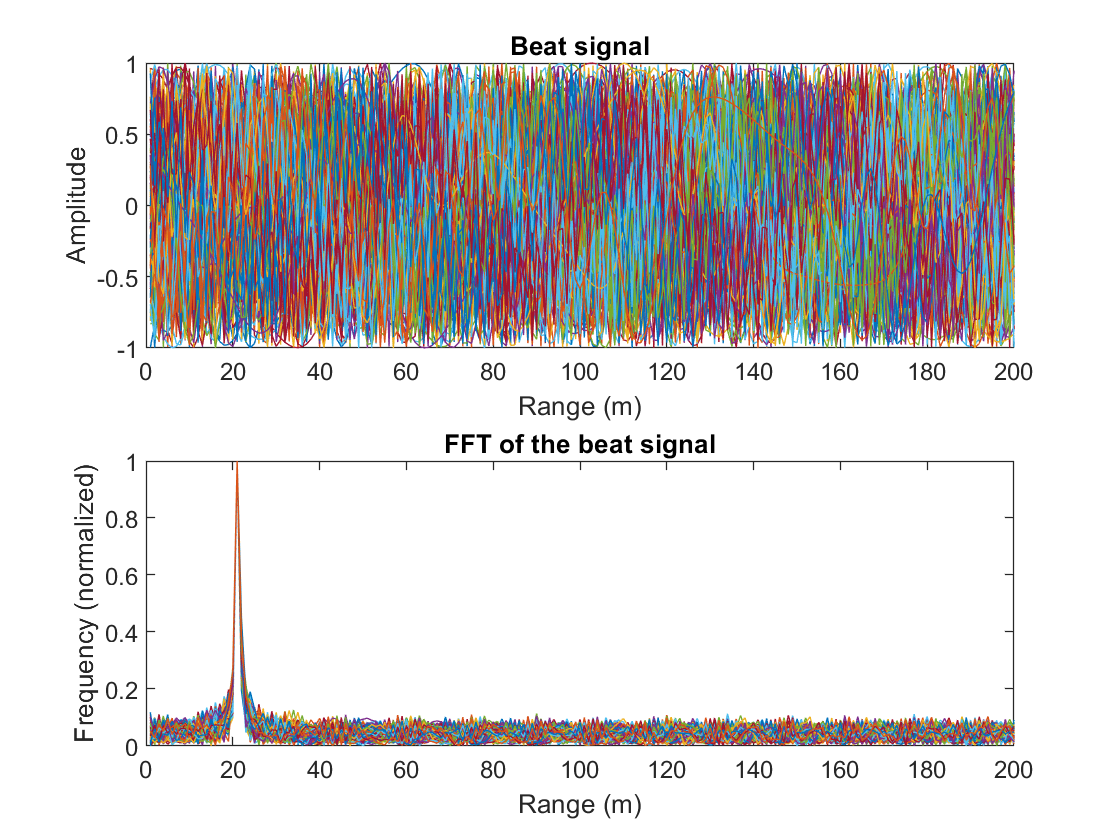

subplot(2,1,1)
plot(Mix)
title("Beat signal")
ylabel("Amplitude")
xlabel("Range (m)")
axis ([0 maxRange -1 1]);

% plot FFT output 
subplot(2,1,2)
plot(fftAlongNrAbsoluteNormalized);
title("FFT of the beat signal")
ylabel("Frequency (normalized)")
xlabel("Range (m)")
axis ([0 maxRange 0 1]);
saveas(oneDimensionalFFTPlot, "./figures/oneDimensionalFFTPlot.png");

## RANGE DOPPLER RESPONSE

The 2D FFT implementation is already provided here. This will run a 2DFFT on the mixed signal (beat signal) output and generate a range doppler map.You will implement CFAR on the generated RDM

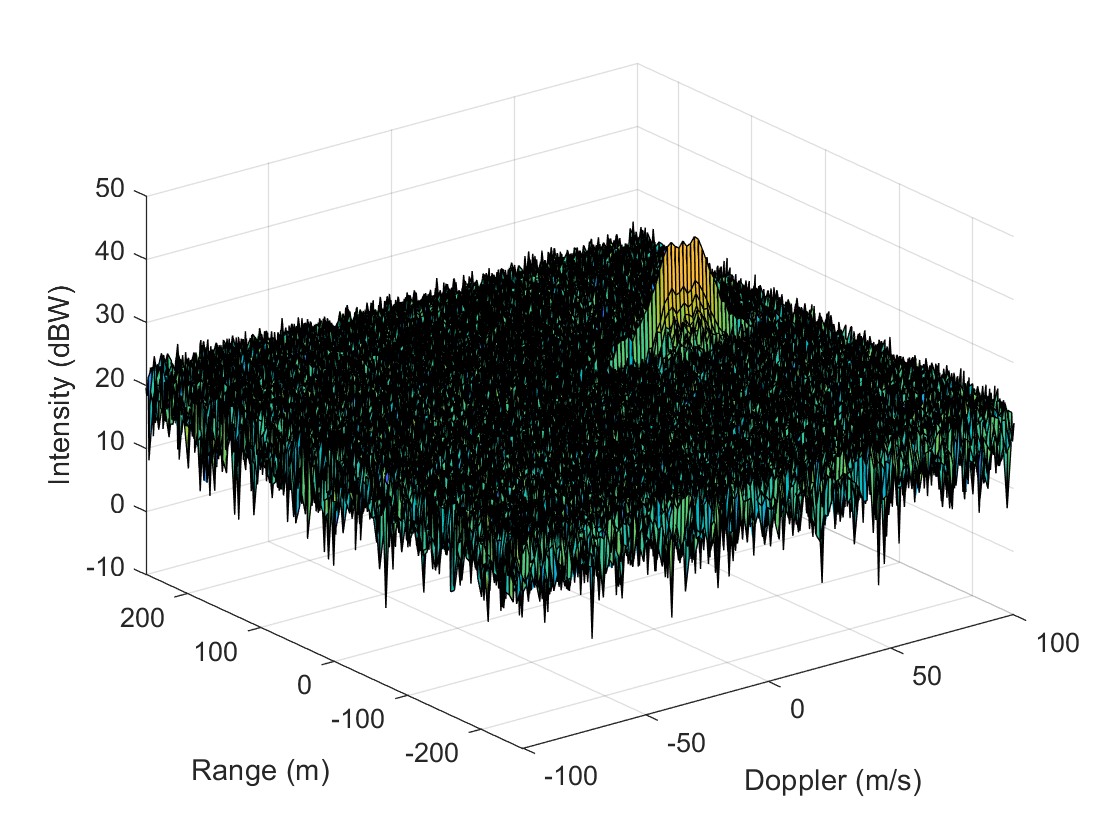

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift(sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);
xlabel("Doppler (m/s)")
ylabel("Range (m)")
zlabel("Intensity (dBW)")

## CFAR implementation

Please see TwoDimensionalCFAR.m

## Hyper-parameter optimization

We will try to optimize the number of [doppler, range] training and guard cells from 0 to 15 for threshold offsets 0, 2, 5, 7, 10, 12, 15, 20, 25.

We will assume that the RDM points at intensity > 35 are the only points that should be in the result.

% offset the threshold by SNR value in dB
thresholdOffsets = [0, 2, 5, 7, 10, 12, 15, 20, 25]; %dB
cellSizes = 0:15;

bestCombinations = [];
tic
for thresholdOffset = thresholdOffsets
    params.thresholdOffset = thresholdOffset;
    params.trainingCellSize = [0, 0]; %[doppler, range]
    params.guardCellSize = [0, 0]; %[doppler, range]
    for dopplerTraining = cellSizes
        params.trainingCellSize(1) = dopplerTraining;
        for rangeTraining = cellSizes
            params.trainingCellSize(2) = rangeTraining;
                for dopplerGuard = cellSizes
                    params.guardCellSize(1) = dopplerGuard;
                    for rangeGuard = cellSizes
                        params.guardCellSize(2) = rangeGuard
                        % run CFAR
                        signal_cfar = TwoDimensionalCFAR(RDM, params.trainingCellSize, params.guardCellSize, params.thresholdOffset, false);
                        if (sum(sum(signal_cfar>35))) > 0
                            bestCombinations = [bestCombinations; params]
                        end
                    end
                end
        end
    end
end
toc
bestCombinations
title('Signal after 2D-CFAR filtering')